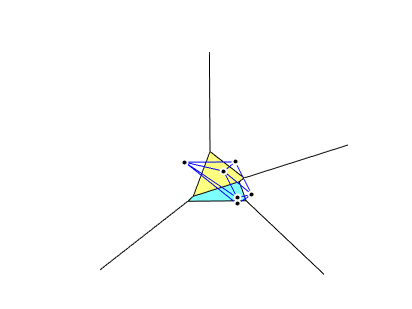

% Given data
rng(2)
X = rand([6,1]);
Y = rand([6,1]);
XY = [X Y];

% Color map with pastel shades
color_map = [1 0 0; % red
             0 1 0; % green
             0 0 1; % blue
             0 1 1; % cyan
             1 0 1; % magenta
             1 1 0]; % yellow

blend_factor = 0.5;
white = [1 1 1];
color_map = color_map + blend_factor * (white - color_map);

% Voronoi diagram and filling
figure;
[vx, vy] = voronoi(X, Y);
plot(vx, vy, '-k'); % Plot Voronoi edges
hold on

% Fill Voronoi regions with pastel colors
[V,C] = voronoin(XY);
for k = 1:length(C)
    if all(C{k}~=1)   % If at least one of the indices is 1, then it is an open region and we can't fill it in.
        patch(V(C{k},1), V(C{k},2), color_map(k,:)); % Use patch to fill region
    end
end

% Delaunay triangulation
DT = delaunay(X,Y);
triplot(DT, X, Y, '-b'); % Plots Delaunay triangulation in blue
scatter(X, Y, 20, 'k', 'o', 'filled', 'MarkerEdgeColor', 'w', 'LineWidth', 1.5); % Plot the original points on top

axis off;